# Quick Start Example: Accessing Neuropixels electrophysiology data from the Allen Brain Observatory

This example demonstrates access and basic analysis of the Visual Coding – Neuropixels dataset [1] from the Allen Brain Observatory web resource [2]. This public dataset consists of muti-channel electrophysiology ('Ephys') experimental recordings, obtained using Neuropixels neural probe technology [3] from the primary visual cortex. 

The Brain Observatory Toolbox consists of functions and classes, contained within its top-level [package folder](https://www.mathworks.com/help/matlab/matlab_oop/scoping-classes-with-packages.html) +bot, which are referenced from MATLAB with the prefix `bot`.

#### Access the Visual Coding - Neuropixels Dataset

The Neuropixels data is grouped and organized by several ***linked dataset items*** of different types - experimental `sessions`, containing data from several `probes` which, in turn, contain data from multiple `channels` and `units`. Each dataset item type can be accessed using the `bot.fetch``LinkedDatasetItemType``()` functions. Information regarding all dataset items of a particular type with item parameters such as unique identifiers (`id`) are available as [tables](https://www.mathworks.com/help/matlab/tables.html). An individual dataset item can be queried from the table (using the row) or as an object (using the item id). Objects come with properties used to inspect information related to that particular dataset item or methods for fetching or analyzing data linked to that particular dataset item.

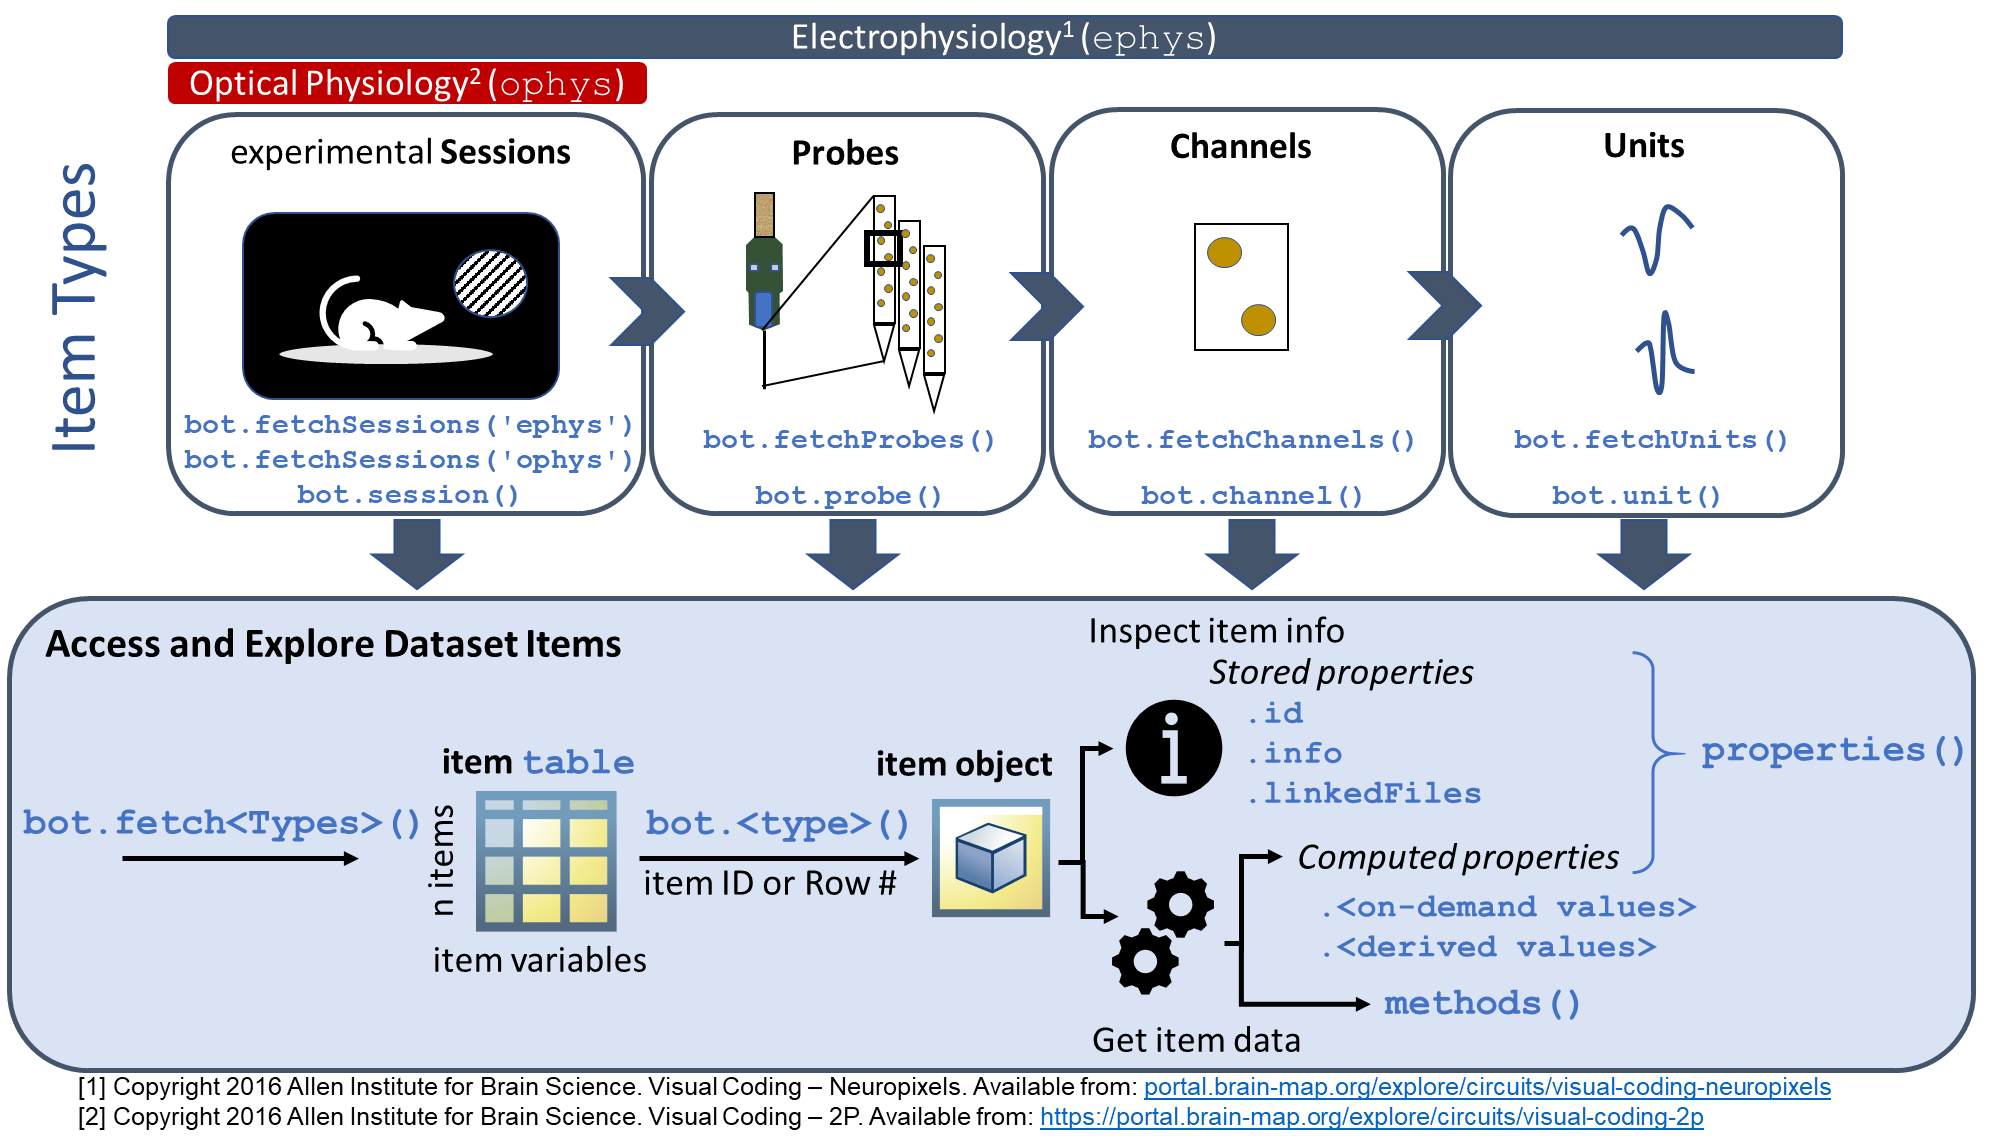

*Fig: Schematic showing relationship of the different *`LinkedDatasetItem`*s to each other and *`bot.fetch`* functions for accessing each.*The Brain Obervatory Toolbox represents the Visual CAll of the available linked dataset contents can be retrieved from the Allen Brain Observatory web resource through a set of `bot.fetch<Types>` functions: 

availSessions = bot.fetchSessions('ephys');
availProbes = bot.fetchProbes();
availChannels = bot.fetchChannels();
availUnits = bot.fetchUnits();

Collectively the retrieved table arrays represent a manifest of the available dataset items organized at varying levels of hierarchy:

- experimental ephys **sessions** 

- associated Neuropixels **probes***, *which recorded ephys data during these sessions

- associated Neuropixels **channels***, *with recorded ephys data physically located along these probes

- inferred neuronal sources, known as **units**, computationally extracted from these channel recordings (via the Visual Coding - Neuropixels data processing pipeline [1])

Inspecting the size of these table arrays with the command `whos` reveals the dataset is quite extensive:

whos availSessions availProbes availChannels availUnits

  Name                    Size                 Bytes  Class    Attributes

  availChannels      123224x33            1732102780  table              
  availProbes           332x26               4852862  table              
  availSessions          58x18                913990  table              
  availUnits          40010x59             630336360  table              



These dataset content tables consists of rows of dataset items whose column-oriented variables contain each item's metadata. Since tables are inherently two-dimensional, their size can also be expressed by their height (number of rows) and width (number of columns). Here the command `height` returns the number of dataset items for a given type: 

disp("There are " + height(availSessions) + " available sessions in the Visual Coding - Neuropixels dataset")

There are 58 available sessions in the Visual Coding - Neuropixels dataset


The Visual Coding - Neuropixels dataset consists of *dozens* of experimental sessions, with recordings from *hundreds* of probes, which capture activity from *tens of thousands *of inferred neuronal units.

#### Inspect Available Sessions 

The `head` command can be used to inspect a table's structure via its first few rows. Let's inspect the available experimental sessions:

head(availSessions)

ans = 8×18 table
    type     date_of_acquisition     fail_eye_tracking       id        isi_experiment_id    published_at    specimen_id        session_type           specimen      well_known_files    age_in_days    sex                      full_genotype                      has_nwb    unit_count    channel_count    probe_count    ephys_structure_acronyms
    _____    ____________________    _________________    _________    _________________    ____________    ___________    _____________________    ____________    ___________

#### Select Sessions of Interest

Table [indexing operations](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html) can be used to select specific experimental sessions (rows) with attributes of interest (column values). For instance, by combining [dot notation with logical indexing](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html#mw_77d04ebd-b6f7-4ee9-93ac-1cc1fd7bc735), we can extract ("filter") sessions with female wild-type subjects that were presented a visual stimulus set designed for investigation of functional connectivity between brain regions [1]: 

filteredSessions = availSessions(availSessions.sex == "F",:); % female subjects
filteredSessions = filteredSessions(filteredSessions.full_genotype == "wt/wt",:); % wild-type subjects
filteredSessions = filteredSessions(filteredSessions.session_type == "functional_connectivity",:); 
disp(filteredSessions)

    type     date_of_acquisition     fail_eye_tracking       id        isi_experiment_id    published_at    specimen_id         session_type            specimen      well_known_files    age_in_days    sex    full_genotype    has_nwb    unit_count    channel_count    probe_count    ephys_structure_acronyms
    _____    ____________________    _________________    _________    _________________    ____________    ___________    _______________________    ____________    ________________    ___________   

From the October 2019 data release, three sessions are found matching the specified attributes of interest. 

#### Create Session Object 

The Brain Observatory Toolbox defines [classes](https://www.mathworks.com/help/matlab/matlab_oop/classes-in-the-matlab-language.html) to represent individual Visual Coding - Neuropixels dataset items as [objects](https://www.mathworks.com/help/matlab/matlab_oop/classes-in-the-matlab-language.html). These objects can inspected and worked with via their defined [properties and methods](https://www.mathworks.com/help/matlab/matlab_oop/classes-in-the-matlab-language.html).

A set of top-level functions (`bot.session`, `bot.probe`, `bot.channel`, `bot.unit)` are provided to create object arrays for dataset items of the corresponding content type. Object creation functions are sometimes called *factory functions*. The `bot.session` factory function can be called to create an object representing the first session item in the `filteredSessions` table above:

These factory functions also can be supplied with a table array, whose rows will be converted to object array elements. For instance, easily create an object for the first session in `filteredSessions` via table indexing:

sessionUnderStudy = bot.session(filteredSessions(1,:)); 

The object has a property `info` providing a [structure](https://www.mathworks.com/help/matlab/ref/struct.html) (field-wise) representation of the values from the table row. This `info `property can be accessed via dot notation: 

sessionUnderStudy.info

ans = struct with fields:
                        type: EPhys
         date_of_acquisition: 08-Feb-2019 09:02:25
           fail_eye_tracking: 0
                          id: 819186360
           isi_experiment_id: 809373390
                published_at: 03-Oct-2019
                 specimen_id: 800249587
                session_type: functional_connectivity
                    specimen: [1×1 struct]
            well_known_files: [1×1 struct]
                 age_in_days: 128
                         sex: F
               full_genotype: "wt/wt"
                     has_nwb: 1
                  unit_count: 531
               channel_count: 1696
                 probe_count: 5
    ephys_structure_acronyms: {19×1 cell}


#### Inspect Session Object Properties

Display the `sessionUnderStudy` object to see its full set of properties, which can provide further access into its underlying data. Scroll through the displayed output to inspect the full set:

disp(sessionUnderStudy)

  ephyssession with properties:

   Metadata
                          metadata: [1×1 struct]
                                id: 819186360
                       age_in_days: 128
                               sex: F
                     full_genotype: "wt/wt"
                      session_type: functional_connectivity
                         num_units: 531
                        num_probes: 5
                      num_channels: 1696

   Contained experimental data
                            probes: [5×26 table]
                          channels: [1696×33 table]
                             units: [531×59 table]

   Lazy loading
                 rig_geometry_data: '[not cached]'
                rig_equipment_name: '[not cached]'
      inter_presentation_intervals: '[not cached]'
                     running_speed: '[not cached]'
                    mean_waveforms: '[not cached]'
            stimulus_

The *NWB data* properties represent direct and computed data values from the underlying data file(s) for the session and would require these data files to be downloaded. Since the Allen Brain Observatory data files, which are in Neurodata without Borders neurophysiology (NWB:N) format [4], can be quite large (sometimes in the GB range), the download is deferred ("on demand") until the property is accessed. 

The *linked data items *properties contain pre-filtered tables for the probe, channel, and unit items that correspond to this experimental session. This session included recordings from 5 probes. Given the high density of Neuropixels ephys probes (384 channels each) [3], these contaim 1696 channels with unit data, from which 531 neuronal units were inferred. 

Inspect the table listing of probes linked to the selected `sessionUnderStudy:`

probesUnderStudy = sessionUnderStudy.probes

probesUnderStudy = 5×26 table
    air_channel_index    ephys_session_id       id        lfp_sampling_rate    lfp_temporal_subsampling_factor       name       phase     sampling_rate    surface_channel_index    has_lfp_data    type     date_of_acquisition     fail_eye_tracking    isi_experiment_id    published_at    specimen_id         session_type            specimen      well_known_files    age_in_days    sex    genotype    has_nwb    unit_count    channel_count    ephys_structure_acronyms
    _________________    ____________

For these 5 probes, the number of channels with valid data ranged from 242 to 371. These `channel_count` values total to 1696, matching the height of the linked `channels` table in the `sessionUnderStudy` object:

sum(probesUnderStudy.channel_count)

ans = 1696

#### Group Analysis of Session Units

The units are computed and scientifically valuable dataset items provided by the Allen Brain Observatory web resouce, allowing some scientific group analysis to be performed without downloading underlying NWB:N data files. 

Access and inspect the table of units linked to the `sessionUnderStudy:`

unitsTable = sessionUnderStudy.units;
head(unitsTable)

ans = 8×59 table
    waveform_PT_ratio    waveform_amplitude    amplitude_cutoff    cumulative_drift     d_prime      waveform_duration    ephys_channel_id    epoch_name_quality_metrics    epoch_name_waveform_metrics    firing_rate    waveform_halfwidth       id        isi_violations    isolation_distance       L_ratio         max_drift     nn_hit_rate     nn_miss_rate     presence_ratio    quality     waveform_recovery_slope    waveform_repolarization_slope    silhouette_score     snr      waveform_spread    waveform_velocity_above    waveform

The units metadata (columns) contains further computed quantities such as the spike firing rate of the inferred neuron. Use `summary` to compute summary statistics across the hundreds of units in the `sessionUnderStudy:`

summary(unitsTable(:,"firing_rate"));

Variables:

    firing_rate: 531×1 double

        Values:

            Min       0.096779
            Median      5.4277
            Max         46.996



The spike firing rate for the inferred neurons varies over a large range from nearly 0 Hz to nearly 50 Hz. A  histogram plot can be used to visualize the statistical distribution:

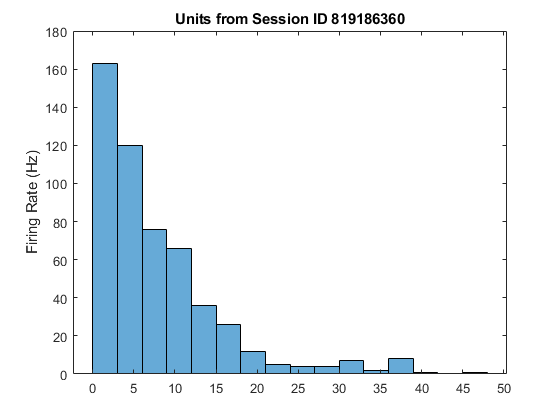

histogram(unitsTable.firing_rate);
ylabel('Firing Rate (Hz)');
title("Units from Session ID " + sessionUnderStudy.id);

The majority of units had firing rates < 10Hz, while the high firing rate units (>30 Hz) form a slightly elevated fraction in the distribution tail for this `sessionUnderStudy`. 

## References

[1] Copyright 2016 Allen Institute for Brain Science. Visual Coding – Neuropixels. Available from: [portal.brain-map.org/explore/circuits/visual-coding-neuropixels](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels).

[2] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 

[3] Information about Neuropixels probes available at [https://neuropixels.org](https://neuropixels.org)

[4] Rubel et al. NWB:N 2.0: An Accessible Data Standard for Neurophysiology. [https://www.biorxiv.org/content/10.1101/523035v1](https://www.biorxiv.org/content/10.1101/523035v1)